U = table2array(dane);
[P_idx, P] = pareto(U, [0 0 1])

P_idx =      4     9    10    13    15


P =          256         108         899
         512         200        6499
         128          50         649
         256          50         699
         512          64        4499


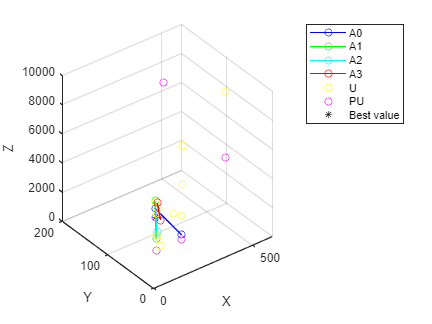

x =    256   108   899


A0 = [256 50 1000; 256 108 1500];
A1 = [128 50 1500; 256 108 2000];
A2 = [128 50 3000; 128 48 2000];
A3 = [64 12 4000;  64 20 5000];
min_max = [false false true];
x = RSM(U, A0, A1, A2, A3, min_max)

function [result, rank] = RSM(U, A0, A1, A2, A3, min_max)
    [P_idx, P] = pareto(U, min_max);
    decisions = size(P, 1);     % Number of decisions
    
    % Checking the integrity of reference points sets
    if ~check_integrity(A0, min_max)
        disp("No integrity in A0 set")
        result = -404;
        return
    end 
    if ~check_integrity(A1, min_max)
        disp("No integrity in A1 set")
        result = -404;
        return
    end
    if ~check_integrity(A2, min_max)
        disp("No integrity in A2 set")
        result = -404;
        return
    end
    if ~check_integrity(A3, min_max)
        disp("No integrity in A3 set")
        result = -404;
        return
    end 

    distance0 = zeros(decisions, size(A0, 1));
    distance1 = zeros(decisions, size(A1, 1));
    distance2 = zeros(decisions, size(A2, 1));
    distance3 = zeros(decisions, size(A3, 1));
    
    for i = 1:decisions
        for j = 1:size(A0, 1)
            distance0(i, j) = norm(P(i, :) - A0(j, :));
        end
        for j = 1:size(A1, 1)
            distance1(i, j) = norm(P(i, :) - A1(j, :));
        end
        for j = 1:size(A2, 1)
            distance2(i, j) = norm(P(i, :) - A2(j, :));
        end
        for j = 1:size(A3, 1)
            distance3(i, j) = norm(P(i, :) - A3(j, :));
        end
    end
       
    scoring_fcn = scoring_function(distance0, distance1, decisions);
    rank = sortrows([P, scoring_fcn], 4);
    result = rank(1, 1:size(rank, 2)-1);
    
    figure;
    plot3(A0(:, 1), A0(:, 2), A0(:, 3), "bo-");          % A0
    hold on;
    grid on;
    plot3(A1(:, 1), A1(:, 2), A1(:, 3), "go-");          % A1
    plot3(A2(:, 1), A2(:, 2), A2(:, 3), "co-");          % A2
    plot3(A3(:, 1), A3(:, 2), A3(:, 3), "ro-");          % A3
    plot3(U(:, 1), U(:, 2), U(:, 3), "yo");              % U 
    plot3(P(:, 1), P(:, 2), P(:, 3), "mo");             % Pareto 
    plot3(result(:,1), result(:, 2), result(:, 3), "k*")      % result
    xlabel("X");
    ylabel("Y");
    zlabel("Z");
    legend("A0", "A1", "A2", "A3", "U", "PU", "Best value")

end

function [pareto_idx, pareto_set] = pareto(U, min_max)
    % min_max is a array of booleans - true means min, false means max
    % Determining pareto set
    U_size = size(U, 1);
    pareto_set = [];
    pareto_idx = [];
    
    for i = 1:U_size
        is_dominated = false;
        for j = 1:U_size
            if i ~= j
                control_sum = 0;
                for col = 1:size(U, 2);
                    if min_max(col)
                        if U(i, col) >= U(j, col)
                            % Checking if point is dominated
                            control_sum = control_sum + 1;
                        end
                    else
                        if U(i, col) <= U(j, col)
                            % Checking if point is dominated
                            control_sum = control_sum + 1;
                        end
                    end
                end

                if control_sum == size(U, 2)
                    is_dominated = true;
                    break;
                end
            end
        end

        if ~is_dominated
            pareto_set = [pareto_set; U(i, :)];
            pareto_idx = [pareto_idx i];
        end
    end
end

function [integrity] = check_integrity(class, min_max)
    % The set that is integral must not contain dominated points 
    class_size = size(class, 1);
    integrity = true;

    for i = 1:class_size
        for j = 1:class_size
            if i ~= j
                control_sum = 0;
                for col = 1:size(class, 2);
                    if min_max(col)
                        if class(i, col) >= class(j, col)
                            % Checking if point is dominated
                            control_sum = control_sum + 1;
                        end
                    else
                        if class(i, col) <= class(j, col)
                            % Checking if point is dominated
                            control_sum = control_sum + 1;
                        end
                    end
                end

                if control_sum == size(class, 2)
                    integrity = false;
                    return
                end
            end
        end
    end
end

function [scoring_result] = scoring_function(distance0, distance1, decisions)
    scoring_result = zeros(decisions, 1);

    for i = 1:decisions
        mean_A0 = mean(distance0(i, :));
        mean_A1 = mean(distance1(i, :));
        scoring_result(i, 1) = mean([mean_A0, mean_A1]);
    end
end